# EE 521 Newton Raphson Power Flow

#### `README`

`Make sure to set MATLAB's working directory as the location of ee521_powerFlow.mlx`

`Currently the NRPF algorithm does NOT support bus type conversion. This obviously affects convergence for bigger bus systems, but fortunately does not seem to affect the 14 and 30 bus systems.`

`Currently it converges for the 14 and 30 bus systems, has trouble with 57 bus system for a couple of buses and blows up for the 118 bus system. I have added another small 3 bus system called koth3 (from Kothari and Nagrath's Modern Power System Analysis) for sanity checks, which converges.`

$N$` bus systems with individual bus numbers `$i$` outside `$[1, N]$`, `$i \in \mathbb{N}$` are currently NOT supported. The ieee300 bus system is one such system.`

### Preamble and Control Inputs

tic;
addpath functions\ %all functions are stored in this folder.
% ieee300 removed from systemName variable options due to poor compatibility. 
% Current algorithm does NOT support N bus systems with bus numbers outside of natural numbers 1 to N.
systemName = "ieee14"; 
folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system
numIterations = 6;
printJacobians = false; %Print Jacobians during NRPF iterations?
printMismatches = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
reducedBranchColumnsCDFReading = true; %Don't read last few branchData columns in CDF files 
% as they are NOT consistent between different CDF files and may cause error in this program.
% (NOTE: Power Flow NOT affected in any way by checking this option.)
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.
% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots
showImages = true; %might add iteration specific images later. 

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranch] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading)

busData = 14×18 table
    bus       busName        loadFlowArea    lossZone    busType    vFinal    deltaFinal     PL      QL      PG       QG      kVBase    Vset     Qmax    Qmin    G     B      remoteControlledBusNumber
    ___    ______________    ____________    ________    _______    ______    __________    ____    ____    _____    _____    ______    _____    ____    ____    _    ____    _

branchData = 20×15 table
    i    j     loadFlowArea    lossZone    ckt    type       R          X         B       MVA1    MVA2    MVA3    controlBusNumber    side      a  
    _    __    ____________    ________    ___    ____    _______    _______    ______    ____    ____    ____    ________________    ____    _____

    1     2         1             1         1      0      0.01938    0.05917    0.0528     0       0       0             0             0          0
    1     5         

N = 14

numBranch = 20

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table.`

[ybus, E] = ybusGenerator(busData, branchData, N, numBranch, disableTaps);
ybusTable = array2table(ybus, VariableNames=[string(1:N)], RowNames=[string(1:N)])

ybusTable = 14×14 table
                 1                  2                 3                 4                  5                  6               7           8              9                 10                 11                 12                13                 14      
          _______________    _______________    ______________    ______________    _______________    _______________    _________    ________    ______________    _______________    _______________    ______________    _______________    ______________

### Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

[PSpecified, QSpecified, V, delta, ...
    listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
    listOfNonSlackBuses] = initializeVectors(busData, N, MVAb);

[P, Q, V, delta] = NRPF(PSpecified, QSpecified, ...
    V, delta, ...
    ybus, E, N, nPQ, nPV, ...
    listOfPQBuses, listOfNonSlackBuses, numIterations,...
    printJacobians, printMismatches);

### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

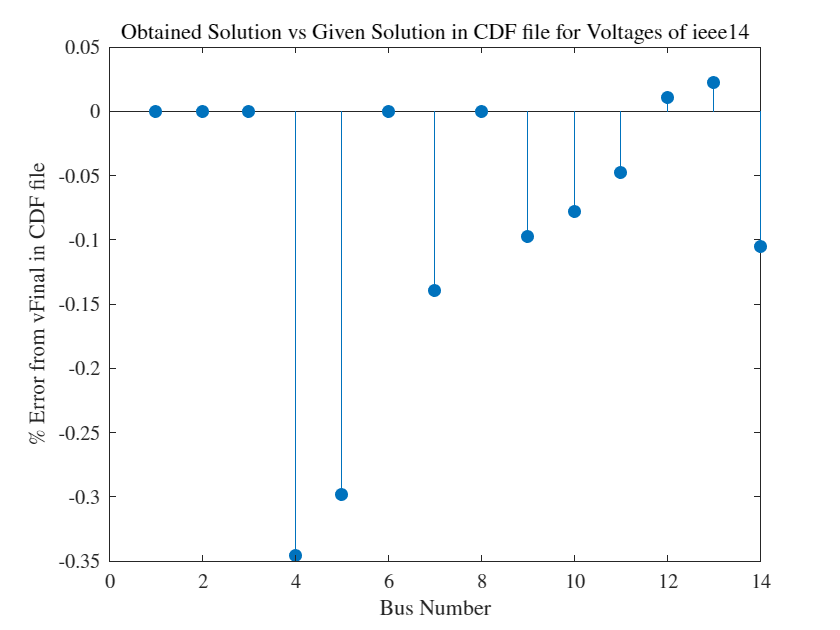

voltagePercentageError = ((V-busData.vFinal)./busData.vFinal)*100;
stem(voltagePercentageError, 'filled');
xlabel('Bus Number');
ylabel('$\%$ Error from vFinal in CDF file');
title('Obtained Solution vs Given Solution in CDF file for Voltages of ' + systemName);

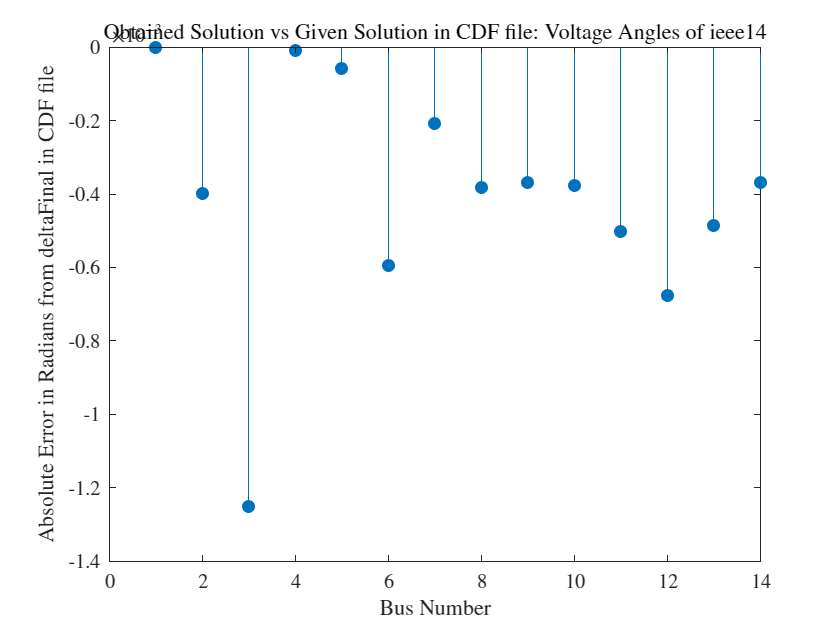


deltaError = delta-(busData.deltaFinal*pi/180);
stem(deltaError, 'filled');
xlabel('Bus Number');
ylabel('Absolute Error in Radians from deltaFinal in CDF file');
title('Obtained Solution vs Given Solution in CDF file: Voltage Angles of ' + systemName);

toc;

Elapsed time is 0.673372 seconds.


# Have a nice day!